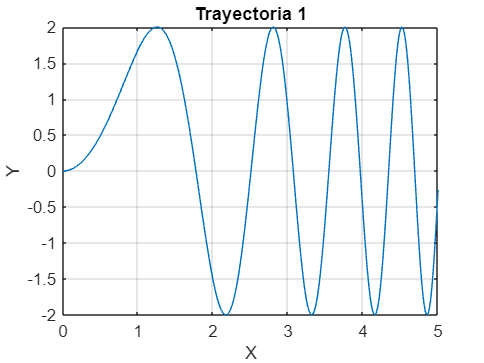

%% ================== TRAYECTORIA 1: Curva sinusoidal ==================

% Definir la trayectoria: y en función de x
x = linspace(0, 5, 400);             % Se generan 400 puntos entre 0 y 5
y = 2 * sin(x.^2);                   % Se evalúa la función y = 2 * sin(x^2)

% Calcular la derivada dy/dx para obtener la dirección de la trayectoria
dy_dx = 4 * x .* cos(x.^2);          % Derivada de y con respecto a x

% Calcular velocidad lineal a partir del módulo del vector tangente
v = sqrt(1 + dy_dx.^2);              % v = sqrt(1 + (dy/dx)^2), módulo del vector tangente

% Calcular ángulo de la trayectoria respecto al eje x
theta = atan(dy_dx);                % Ángulo instantáneo de orientación

% Graficar la trayectoria
plot(x, y);                          % Traza la curva
title('Trayectoria 1');             
xlabel('X');
ylabel('Y');
grid on;

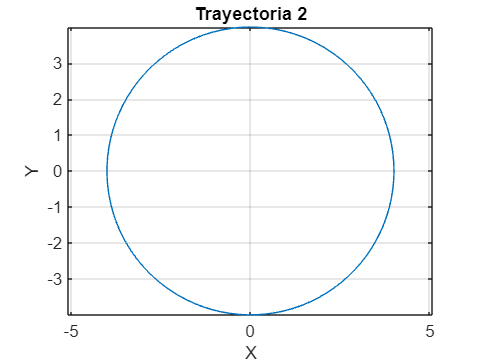



%% ================== TRAYECTORIA 2: Movimiento circular ==================

% Parámetros del círculo
r = 4;                               % Radio del círculo
omega = 1;                           % Velocidad angular constante (rad/s)
v = r * omega;                       % Velocidad lineal constante

% Definir los ángulos theta a lo largo del círculo
theta = linspace(0, 2*pi, 100);      % De 0 a 2pi en 100 puntos

% Calcular coordenadas x e y del círculo
x = r * cos(theta);                 
y = r * sin(theta);                 

% Calcular componentes de velocidad tangencial
vx = -v * sin(theta);               % Componente horizontal de la velocidad
vy = v * cos(theta);                % Componente vertical de la velocidad

% Graficar la trayectoria circular
figure;
plot(x, y);                          % Dibuja el círculo
hold on;
axis equal;                          % Mantiene proporción real en X e Y
title('Trayectoria 2');
xlabel('X');
ylabel('Y');
grid on;

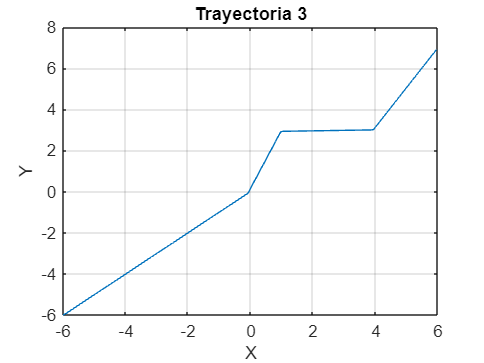



%% ================== TRAYECTORIA 3: Camino por puntos ==================

% Definir puntos por los que debe pasar el robot
puntos = [-6 -6; 0 0; 1 3; 4 3; 6 7];  % Lista de puntos objetivo (X,Y)

% Posición y orientación inicial del robot
x = -6;
y = -6;
theta = 0;                            % Ángulo inicial

% Parámetros de simulación
v = 0.05;                             % Velocidad lineal constante
dt = 0.01;                            % Paso de integración (tiempo)

% Inicializar vectores para guardar la trayectoria
x_result = x;
y_result = y;

% Recorrer todos los puntos intermedios definidos
for i = 1:size(puntos,1)-1
    % Extraer siguiente punto objetivo
    x_target = puntos(i+1, 1);
    y_target = puntos(i+1, 2);
    
    % Bucle que simula el movimiento hasta alcanzar el objetivo
    while true
        % Calcular el ángulo hacia el punto objetivo
        target_angle = atan2(y_target - y, x_target - x);
        
        % Calcular diferencia entre ángulo objetivo y orientación actual
        angle_diff = target_angle - theta;

        % Control proporcional para ajustar la orientación
        omega = 2 * angle_diff;        % Control tipo P: omega = Kp * error

        % Actualizar orientación y posición del robot
        theta = theta + omega * dt;               % Nueva orientación
        x = x + v * cos(theta) * dt;              % Movimiento en X
        y = y + v * sin(theta) * dt;              % Movimiento en Y
        
        % Guardar la posición actual
        x_result = [x_result, x];
        y_result = [y_result, y];
        
        % Condición de parada (cuando está suficientemente cerca)
        if abs(x - x_target) < 0.1 && abs(y - y_target) < 0.1
            break;
        end
    end
end

% Graficar la trayectoria generada entre los puntos
figure;
plot(x_result, y_result);
hold on;
title('Trayectoria 3');
xlabel('X');
ylabel('Y');
grid on;